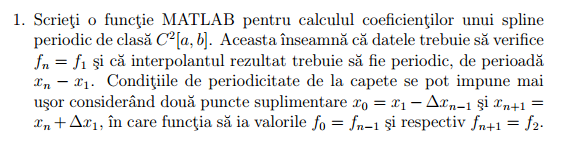

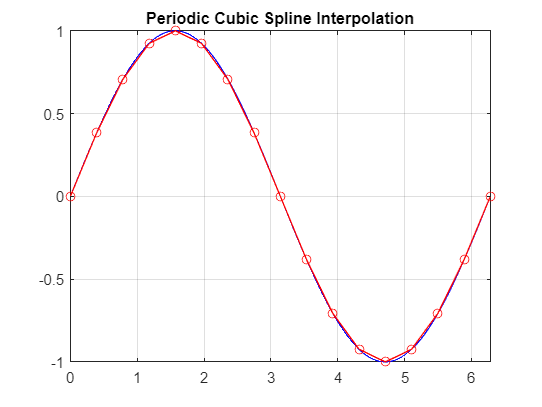

x = linspace(0, 2*pi, 17);     % 16 intervals, periodic domain
y = sin(x); y(end) = y(1);    % Ensure periodic values

S = spline_periodic(x, y);    % Construct periodic spline
xx = linspace(0, 2*pi, 1000);

figure;
plot(xx, S(xx), 'b', x, y, 'ro-');
title('Periodic Cubic Spline Interpolation');
grid on; axis tight;